# Project GP2

## Q1.1

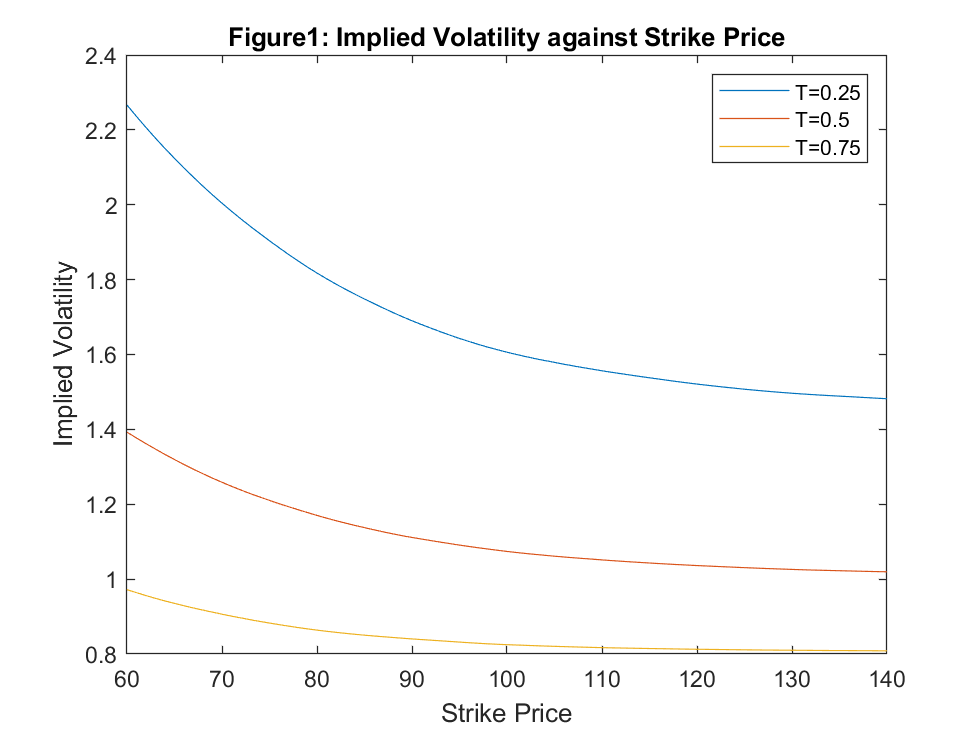

T=[0.25,0.5,0.75];
S0=100;r=0.05;sig=0.35;lambda=2;N=1e3;
gamma=0;eta=0.4;kbar=exp(gamma+eta^2/2)-1;
ST=zeros(length(T),N);
for j=1:N
      Nt=poissrnd(lambda,1);
      log_Ynt=normrnd(gamma,eta,1,Nt);
      Z=normrnd(0,1,1);%%common random numbers
  for i=1:length(T)
      ST(i,j)=S0*exp((r-lambda*kbar-sig^2/2)*T(i)+sig*...
          sqrt(T(i))*Z+sum(log_Ynt));
  end
end
imv=zeros(length(T),81);
for K=60:140
    for i=1:length(T)
        CJD=exp(-r*T(i))*mean(max(ST(i,:)-K,0));
        imv(i,K-59)=blsimpv(S0,K,r,T(i),CJD);
    end
end    
plot(60:140,imv(1,:),60:140,imv(2,:),60:140,imv(3,:))
title("Figure1: Implied Volatility against Strike Price")
xlabel("Strike Price")
ylabel("Implied Volatility")
legend("T=0.25","T=0.5","T=0.75")

## Q1.2

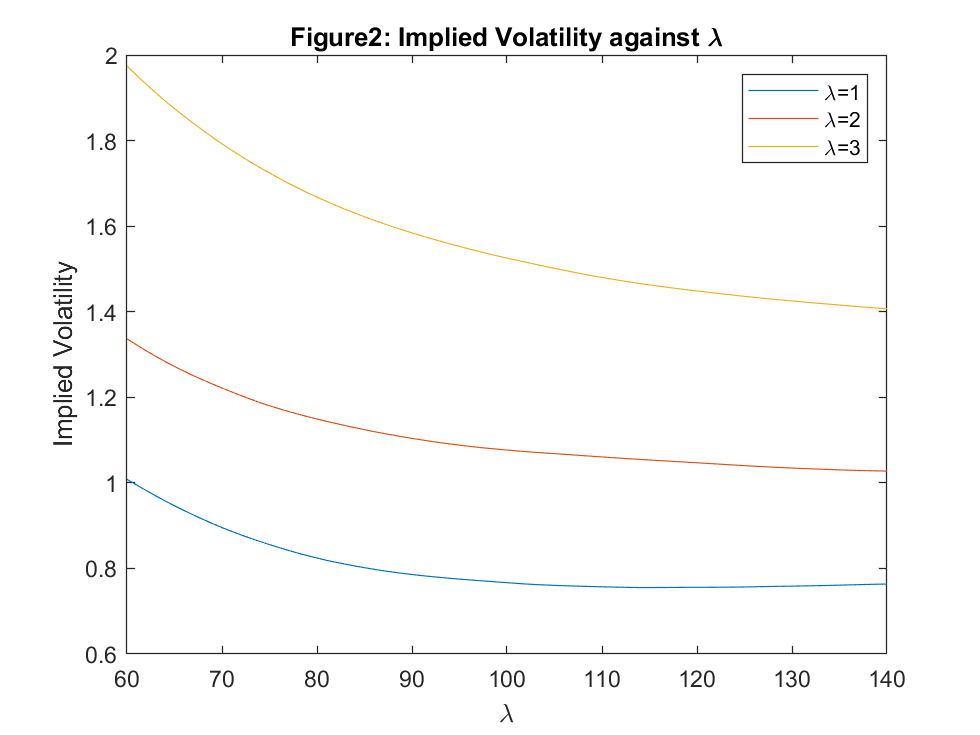

lambda=[1,2,3];
S0=100;r=0.05;sig=0.35;T=0.5;N=1e3;
gamma=0;eta=0.4;kbar=exp(gamma+eta^2/2)-1;
ST=zeros(length(lambda),N);
for j=1:N
  for i=1:length(lambda)
      Nt=poissrnd(lambda(i),1);
      log_Ynt=normrnd(gamma,eta,1,Nt);
      Z=normrnd(0,1,1);%%common random numbers
      ST(i,j)=S0*exp((r-lambda(i)*kbar-sig^2/2)*T+sig*...
          sqrt(T)*Z+sum(log_Ynt));
  end
end
imv=zeros(length(lambda),81);
for K=60:140
    for i=1:length(lambda)
        CJD=exp(-r*T)*mean(max(ST(i,:)-K,0));
        imv(i,K-59)=blsimpv(S0,K,r,T,CJD);
    end
end    
plot(60:140,imv(1,:),60:140,imv(2,:),60:140,imv(3,:))
title("Figure2: Implied Volatility against \lambda")
xlabel("\lambda")
ylabel("Implied Volatility")
legend("\lambda=1","\lambda=2","\lambda=3")

## Q1.3

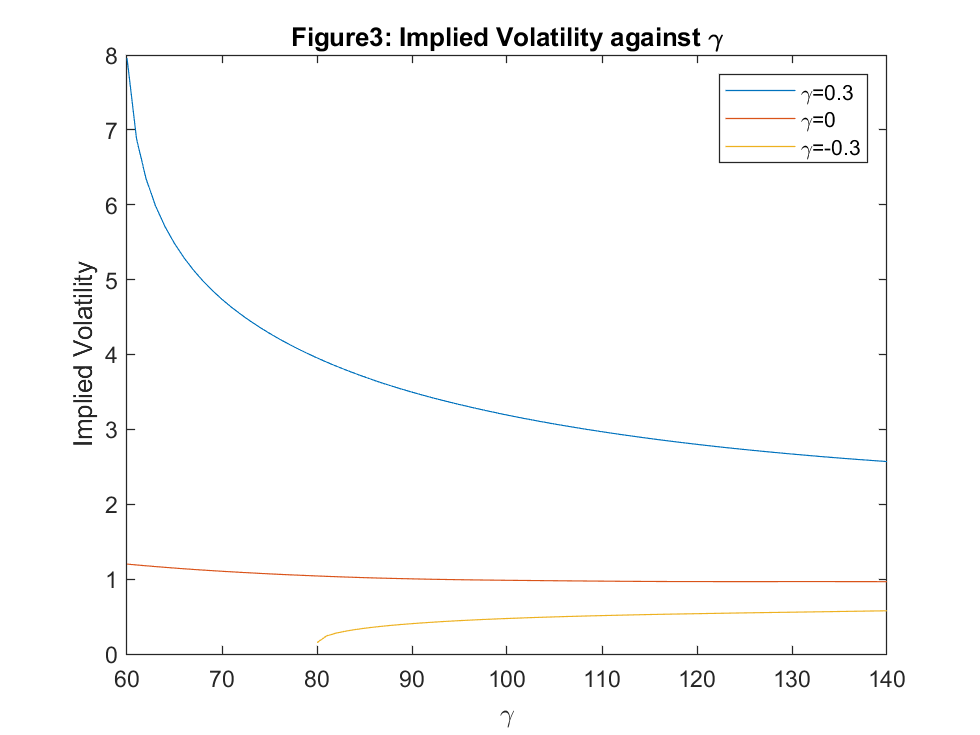

gamma=[0.3,0,-0.3];
S0=100;r=0.05;sig=0.35;T=0.5;N=1e3;
lambda=2;eta=0.4;
ST=zeros(length(gamma),N);
for j=1:N
    Nt=poissrnd(lambda,1);
  for i=1:length(gamma)
      kbar=exp(gamma(i)+eta^2/2)-1;
      log_Ynt=normrnd(gamma(i),eta,1,Nt);
      Z=normrnd(0,1,1);%%common random numbers
      ST(i,j)=S0*exp((r-lambda*kbar-sig^2/2)*T+sig*...
          sqrt(T)*Z+sum(log_Ynt));
  end
end
imv=zeros(length(gamma),81);
for K=60:140
    for i=1:length(gamma)
        CJD=exp(-r*T)*mean(max(ST(i,:)-K,0));
        imv(i,K-59)=blsimpv(S0,K,r,T,CJD);
    end
end    
plot(60:140,imv(1,:),60:140,imv(2,:),60:140,imv(3,:))
title("Figure3: Implied Volatility against \gamma")
xlabel("\gamma")
ylabel("Implied Volatility")
legend("\gamma=0.3","\gamma=0","\gamma=-0.3")

## Q1.4

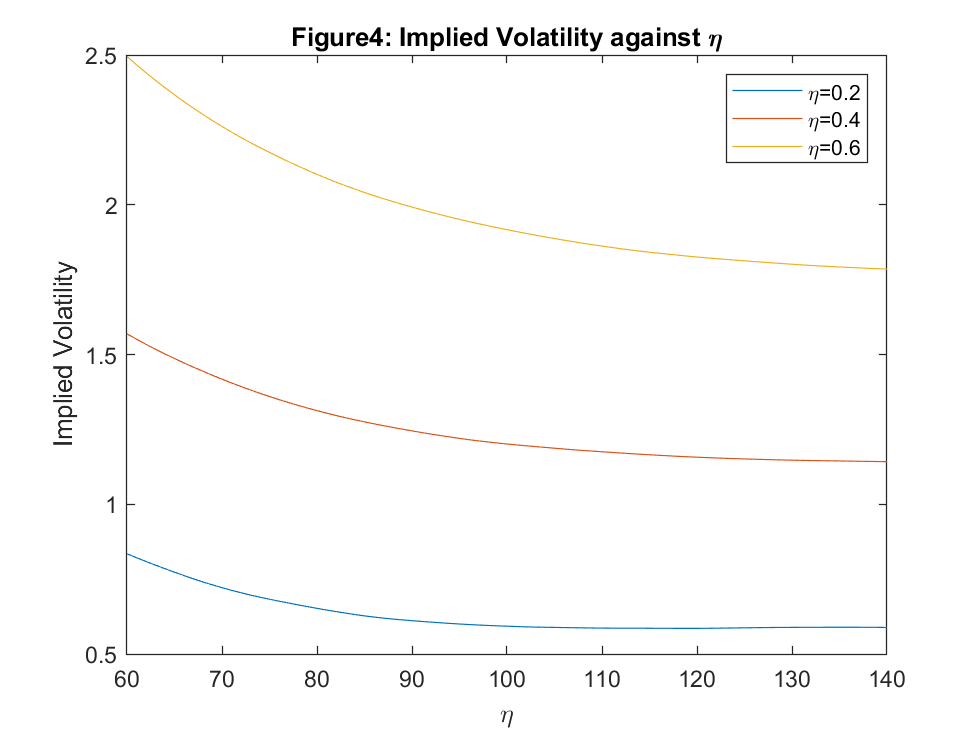

eta=[0.2,0.4,0.6];
S0=100;r=0.05;sig=0.35;T=0.5;N=1e3;
lambda=2;gamma=0;
ST=zeros(length(eta),N);
for j=1:N
    Nt=poissrnd(lambda,1);
  for i=1:length(eta)
      kbar=exp(gamma+eta(i)^2/2)-1;
      log_Ynt=normrnd(gamma,eta(i),1,Nt);
      Z=normrnd(0,1,1);%%common random numbers
      ST(i,j)=S0*exp((r-lambda*kbar-sig^2/2)*T+sig*...
          sqrt(T)*Z+sum(log_Ynt));
  end
end
imv=zeros(length(eta),81);
for K=60:140
    for i=1:length(eta)
        CJD=exp(-r*T)*mean(max(ST(i,:)-K,0));
        imv(i,K-59)=blsimpv(S0,K,r,T,CJD);
    end
end    
plot(60:140,imv(1,:),60:140,imv(2,:),60:140,imv(3,:))
title("Figure4: Implied Volatility against \eta")
xlabel("\eta")
ylabel("Implied Volatility")
legend("\eta=0.2","\eta=0.4","\eta=0.6")

## Q2.a.1

clear;
r=0.05;delta=0.02;sig=0.3;S0=[100,100,100];
K=100;T=1;N=1e3;m=1000;dt=T/m;
cor_a=ones(3,3)*0.2;
for i=1:3
    cor_a(i,i)=1;
end
C_a=chol(cor_a);
ST{1}=zeros(m+1,N);ST{2}=zeros(m+1,N);ST{3}=zeros(m+1,N);
ST{1}(1,:)=S0(1)*ones(1,N);ST{2}(1,:)=S0(2)*ones(1,N);ST{3}(1,:)=S0(3)*ones(1,N);
for i=1:N
    Z0=normrnd(0,1,m,3);Z=Z0*C_a;
    for j=2:m+1
        ST{1}(j,i)=ST{1}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z(j-1,1));
        ST{2}(j,i)=ST{2}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z(j-1,2));
        ST{3}(j,i)=ST{3}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z(j-1,3));
    end
end
payoff=zeros(1,N);
for j=1:N
    payoff(j)=max(K-min([ST{1}(m+1,j),ST{2}(m+1,j),ST{3}(m+1,j)]),0);
end
%%standard MC method
P_standard=exp(-r*T)*mean(payoff);P_standard

P_standard = 20.1362

std(payoff)/sqrt(N)

ans = 0.5016

## Q2.a.2

%%control variate method, choose Y's payoff (K-ST1)+
Y=(max(K-ST{1}(m+1,:),0))';Ybar=exp(-r*T)*mean(Y);
b=std(payoff)/std(Y)*corr(Y,payoff');
P_variate=exp(-r*T)*mean(payoff)-b*(Ybar-...
    blsprice(S0(1),K,r,T,sig)+S0(1)-K*exp(-r*T))

P_variate = 19.5696

%%call put parity
sqrt(std(Y)^2+b^2*std(payoff)^2-2*b*corr(Y,payoff')*...
    std(payoff)*std(Y))/sqrt(N)

ans = 0.3649


%%control variate method, choose Y's payoff mean of (K-ST1,2,3)+
Y=((max(K-ST{1}(m+1,:),0)+max(K-ST{2}(m+1,:),0)+max(K-ST{3}(m+1,:),0))/3)';
Ybar=exp(-r*T)*mean(Y);b=std(payoff)/std(Y)*corr(Y,payoff');
P_variate_modi=exp(-r*T)*mean(payoff)-b*(Ybar-...
    blsprice(S0(1),K,r,T,sig)/3-blsprice(S0(2),K,r,T,sig)/3-...
    blsprice(S0(3),K,r,T,sig)/3+S0(1)/3+S0(2)/3+S0(3)/3-...
    K*exp(-r*T));P_variate_modi

P_variate_modi = 19.2673

%%call put parity
sqrt(std(Y)^2+b^2*std(payoff)^2-2*b*corr(Y,payoff')*...
    std(payoff)*std(Y))/sqrt(N)

ans = 0.5348


%%antithetic variates method, choose Z and -Z
r=0.05;delta=0.02;sig=0.3;S0=[100,100,100];
K=100;T=1;N=1e3;m=1000;dt=T/m;
ST{1}=zeros(m+1,N/2);ST{2}=zeros(m+1,N/2);ST{3}=zeros(m+1,N/2);
ST{11}=zeros(m+1,N/2);ST{22}=zeros(m+1,N/2);ST{33}=zeros(m+1,N/2);
ST{1}(1,:)=S0(1)*ones(1,N/2);ST{2}(1,:)=S0(2)*ones(1,N/2);ST{3}(1,:)=S0(3)*ones(1,N/2);
ST{11}(1,:)=S0(1)*ones(1,N/2);ST{22}(1,:)=S0(2)*ones(1,N/2);ST{33}(1,:)=S0(3)*ones(1,N/2);
for i=1:N/2
    Z0=normrnd(0,1,m,3);Z1=Z0*C_a;Z2=-Z0*C_a;
    for j=2:m+1
        ST{1}(j,i)=ST{1}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z1(j-1,1));
        ST{2}(j,i)=ST{2}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z1(j-1,2));
        ST{3}(j,i)=ST{3}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z1(j-1,3));
        ST{11}(j,i)=ST{1}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z2(j-1,1));
        ST{22}(j,i)=ST{2}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z2(j-1,2));
        ST{33}(j,i)=ST{3}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z2(j-1,3));
    end
end
payoff1=zeros(1,N/2);payoff2=zeros(1,N/2);
for j=1:N/2
    payoff1(j)=max(K-min([ST{1}(m+1,j),ST{2}(m+1,j),ST{3}(m+1,j)]),0);
    payoff2(j)=max(K-min([ST{11}(m+1,j),ST{22}(m+1,j),ST{33}(m+1,j)]),0);
end
P_antithetic=exp(-r*T)*(sum(payoff1)+sum(payoff2))/N;
P_antithetic

P_antithetic = 19.2211

covariance=cov(payoff1,payoff2);
sqrt(var(payoff1)+var(payoff2)+2*covariance(2))/sqrt(N)/2

ans = 0.4941

## Q2.a.3

%%low-discrepancy numbers
r=0.05;delta=0.02;sig=0.3;S0=[100,100,100];
K=100;T=1;N=1e3;
s=sobolset(3);X=net(s,N);
%% use U to get Z
Z=zeros(N,3);ST=zeros(N,3);
for i=1:3
    Z(:,i)=norminv(X(:,i));
end
Z=Z*C_a;
for i=1:3
    ST(:,i)=S0(i).*exp((r-delta-0.5*sig^2)*T+sig*sqrt(T).*Z(:,i));
end
payoff=zeros(1,N);
for j=1:N
    payoff(j)=max(K-min(ST(j,:)),0);
end
P_low=exp(-r*T)*mean(payoff);P_low

P_low = 20.3515

std(payoff)/sqrt(N)

ans = 0.4993

## Q2.b.1

clear;
r=0.05;delta=0.02;sig=0.3;S0=[100,100,100,100,100];
K=100;T=1;N=1e3;m=1000;dt=T/m;
cor_b=ones(5,5)*0.5;
for i=1:5
    cor_b(i,i)=1;
end
C_b=chol(cor_b);
ST{1}=zeros(m+1,N);ST{2}=zeros(m+1,N);ST{3}=zeros(m+1,N);ST{4}=zeros(m+1,N);ST{5}=zeros(m+1,N);
ST{1}(1,:)=S0(1)*ones(1,N);ST{2}(1,:)=S0(2)*ones(1,N);ST{3}(1,:)=S0(3)*ones(1,N);
ST{4}(1,:)=S0(4)*ones(1,N);ST{5}(1,:)=S0(5)*ones(1,N);
for i=1:N
    Z0=normrnd(0,1,m,5);Z=Z0*C_b;
    for j=2:m+1
        ST{1}(j,i)=ST{1}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z(j-1,1));
        ST{2}(j,i)=ST{2}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z(j-1,2));
        ST{3}(j,i)=ST{3}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z(j-1,3));
        ST{4}(j,i)=ST{4}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z(j-1,4));
        ST{5}(j,i)=ST{5}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z(j-1,5));
    end
end
payoff=zeros(1,N);
for j=1:N
    payoff(j)=max(ST{1}(m+1,j)+ST{2}(m+1,j)+ST{3}(m+1,j)-ST{4}(m+1,j)-ST{5}(m+1,j)-K,0);
end
%%standard MC method
P_standard=exp(-r*T)*mean(payoff)

P_standard = 21.9710

std(payoff)/sqrt(N)

ans = 1.1407

## Q2.b.2

%%control variate method, choose Y's payoff  
% call for stock ST1,2,3 - ST4,5
Y=max(ST{1}(m+1,:)-K,0)+max(ST{2}(m+1,:)-K,0)+max(ST{3}(m+1,:)-K,0)-...
    max(ST{4}(m+1,:)-K,0)-max(ST{5}(m+1,:)-K,0);
Ybar=exp(-r*T)*mean(Y);b=std(payoff)/std(Y)*corr(Y',payoff');
%%due to the five stock are relatively the same
% so E(Y) equals to one call price of stock
P_variate_modi=exp(-r*T)*mean(payoff)-b*(Ybar-...
    blsprice(S0(1),K,r,T,sig))

P_variate_modi = 22.8944

%%call put parity
sqrt(std(Y)^2+b^2*std(payoff)^2-2*b*corr(Y',payoff')*...
    std(payoff)*std(Y))/sqrt(N)

ans = 0.6542


%%antithetic variates method, choose Z and -Z
r=0.05;delta=0.02;sig=0.3;S0=[100,100,100,100,100];
K=100;T=1;N=1e3;m=1000;dt=T/m;
ST{1}=zeros(m+1,N/2);ST{2}=zeros(m+1,N/2);ST{3}=zeros(m+1,N/2);ST{4}=zeros(m+1,N/2);ST{5}=zeros(m+1,N/2);
ST{1}(1,:)=S0(1)*ones(1,N/2);ST{2}(1,:)=S0(2)*ones(1,N/2);ST{3}(1,:)=S0(3)*ones(1,N/2);
ST{4}(1,:)=S0(4)*ones(1,N/2);ST{5}(1,:)=S0(5)*ones(1,N/2);
ST{11}=zeros(m+1,N/2);ST{22}=zeros(m+1,N/2);ST{33}=zeros(m+1,N/2);ST{44}=zeros(m+1,N/2);ST{55}=zeros(m+1,N/2);
ST{11}(1,:)=S0(1)*ones(1,N/2);ST{22}(1,:)=S0(2)*ones(1,N/2);ST{33}(1,:)=S0(3)*ones(1,N/2);
ST{44}(1,:)=S0(4)*ones(1,N/2);ST{55}(1,:)=S0(5)*ones(1,N/2);
for i=1:N/2
    Z0=normrnd(0,1,m,5);Z1=Z0*C_b;Z2=-Z0*C_b;
    for j=2:m+1
        ST{1}(j,i)=ST{1}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z1(j-1,1));
        ST{2}(j,i)=ST{2}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z1(j-1,2));
        ST{3}(j,i)=ST{3}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z1(j-1,3));
        ST{4}(j,i)=ST{4}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z1(j-1,4));
        ST{5}(j,i)=ST{5}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z1(j-1,5));
        ST{11}(j,i)=ST{11}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z2(j-1,1));
        ST{22}(j,i)=ST{22}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z2(j-1,2));
        ST{33}(j,i)=ST{33}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z2(j-1,3));
        ST{44}(j,i)=ST{44}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z2(j-1,4));
        ST{55}(j,i)=ST{55}(j-1,i)*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*Z2(j-1,5));
    end
end
payoff1=zeros(1,N);payoff2=zeros(1,N);
for j=1:N/2
    payoff1(j)=max(ST{1}(m+1,j)+ST{2}(m+1,j)+ST{3}(m+1,j)-ST{4}(m+1,j)-ST{5}(m+1,j)-K,0);
    payoff2(j)=max(ST{11}(m+1,j)+ST{22}(m+1,j)+ST{33}(m+1,j)-ST{44}(m+1,j)-ST{55}(m+1,j)-K,0);
end
P_antithetic=exp(-r*T)*(sum(payoff1)+sum(payoff2))/N

P_antithetic = 21.2297

covariance=cov(payoff1,payoff2);
sqrt(var(payoff1)+var(payoff2)+2*covariance(2))/sqrt(N)/2

ans = 0.5355

## Q2.b.3

%%low-discrepancy numbers
r=0.05;delta=0.02;sig=0.3;S0=[100,100,100,100,100];
K=100;T=1;N=1e3;
s=sobolset(5);X=net(s,N);
%% use U to get Z
Z=zeros(N,5);ST=zeros(N,5);
for i=1:5
    Z(:,i)=norminv(X(:,i));
end
Z=Z*C_b;
for i=1:5
    ST(:,i)=S0(i).*exp((r-delta-0.5*sig^2)*T+sig*sqrt(T).*Z(:,i));
end
payoff=zeros(1,N);
for j=1:N
    payoff(j)=max(ST(j,1)+ST(j,2)+ST(j,3)-ST(j,4)-ST(j,5)-K,0);
end
P_low=exp(-r*T)*mean(payoff)

P_low = 21.5244

std(payoff)/sqrt(N)

ans = 1.1387

## Q2.c

r=0.05;delta=0.02;sig=0.3;S10=100;S20=100;rho=-0.1;
%% psi{1,S1,S2,S1^2,S2^2,S1*S2}
M=6;K=100;T=1;N=1e3;m=10;dt=T/m;
S1=zeros(m,N);S2=zeros(m,N);
for i=1:m %%time steps
    X1=normrnd(0,1,1,N);
    S1(i,1:N)=S10.*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*X1);
    S10=S1(i,1:N);
    X2=normrnd(0,1,1,N);
    X3=rho*X1+sqrt(1-rho^2)*X2;
    S2(i,1:N)=S20.*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*X3);
    S20=S2(i,1:N);
end

V=zeros(m,N);
V(m,1:N)=max(K-min(S1(m,1:N),S2(m,1:N)),0);
%% define the option value if it is exercised at the maturity

%% define the option value if it exercises early

for i=(m-1):-1:1
    psi=zeros(M,N);
    psi(1,1:N)=ones(1,N);
    psi(2,1:N)=S1(i,1:N);
    psi(3,1:N)=S2(i,1:N);
    psi(4,1:N)=S1(i,1:N).^2;
    psi(5,1:N)=S2(i,1:N).^2;
    psi(6,1:N)=S1(i,1:N).^S2(i,1:N);

    Bpsi=psi*(psi)';
    beta=Bpsi\(psi*V(i+1,1:N)'); %%A^-1.*B = A\B
    CV=exp(-r*dt)*beta'*psi;
    V(i,1:N)=max(max(K-min(S1(i,1:N),S2(i,1:N)),0),CV);
end

price=exp(-r*dt)*mean(V(1,:));price

price = 8.7921

## Q2.d

r=0.05;delta=0.02;sig=0.3;
S10=100;S20=100;S30=100;rho=0.3;
%% psi{1,S1,S2,S3,S1*S2,S2*S3,S1*S3,S1^2,S2^2,S3^2}
M=10;K=100;T=1;N=1e3;m=10;dt=T/m;
S1=zeros(m,N);S2=zeros(m,N);S3=zeros(m,N);
%% get the Cholesky factorization
cor=ones(3,3)*0.3;
for i=1:3
    cor(i,i)=1;
end
C=chol(cor);
for i=1:m %%time steps
    Z=normrnd(0,1,3,N);X=(Z'*C)';
    S1(i,1:N)=S10.*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*X(1,:));
    S10=S1(i,1:N);
    S2(i,1:N)=S20.*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*X(2,:));
    S20=S2(i,1:N);
    S3(i,1:N)=S30.*exp((r-delta-0.5*sig^2)*dt+sig*sqrt(dt)*X(3,:));
    S30=S3(i,1:N);
end

V=zeros(m,N);
V(m,1:N)=max(S1(m,1:N)+S2(m,1:N)-S3(m,1:N)-K,0);
%% define the option value if it is exercised at the maturity

%% define the option value if it exercises early

for i=(m-1):-1:1
    psi=zeros(M,N);
    psi(1,1:N)=ones(1,N);
    psi(2,1:N)=S1(i,1:N);
    psi(3,1:N)=S2(i,1:N);
    psi(4,1:N)=S3(i,1:N);
    psi(5,1:N)=S1(i,1:N).*S2(i,1:N);
    psi(6,1:N)=S2(i,1:N).*S3(i,1:N);
    psi(7,1:N)=S1(i,1:N).*S3(i,1:N);
    psi(8,1:N)=S1(i,1:N).^2;
    psi(9,1:N)=S2(i,1:N).^2;
    psi(10,1:N)=S3(i,1:N).^2;
    
    Bpsi=psi*(psi)';
    beta=Bpsi\(psi*V(i+1,1:N)'); %%A^-1.*B = A\B
    CV=exp(-r*dt)*beta'*psi;
    V(i,1:N)=max(max(S1(i,1:N)+S2(i,1:N)-S3(i,1:N)-K,0),CV);
end
exp(-r*dt)*mean(V(1,:))

ans = 20.3231